# Práctica 1 Model. Exp.

María Sofía Uribe

Juan Pablo Ossa

Es necesario cargar los datos suministrados por la empresa en este punto

load data2.mat

## 1. Planteamiento del problema (Petición de la empresa)

Cordial saludo ingenieros matemáticos. Nos comunicamos con ustedes porque necesitamos determinar un modelo para el comportamiento de cierta planta ultra secreta. Como podrán comprender, nos vemos en la obligación de reservarnos la mayor cantidad de información posible. Nosotros mismos ya hemos adelantado parte de los procesos necesarios para determinar el modelo. Sabemos que nuestra planta consta de una única entrada y una única salida, la entrada tiene un valor de 1000 unidades regularmente y la planta se mantiene en estado estacionario. Partiendo de este punto de estabilidad, nuestro anterior ingeniero varió el valor de la entrada en un rango de 500 a 1500 tal y como pueden ver a continuación

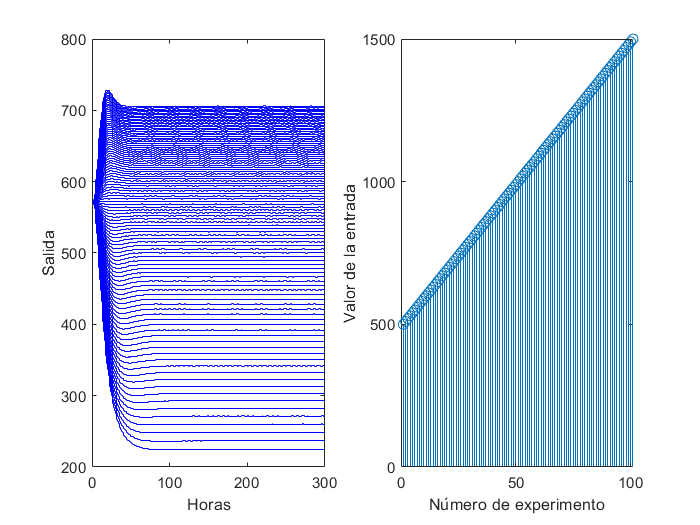

figure(1)
clf
subplot(1,2,1)
stairs(0:300,y_sample','b')
xlabel('Horas')
ylabel('Salida')
subplot(1,2,2)
stem(u_lineal)
xlabel('Número de experimento')
ylabel('Valor de la entrada')

**                                        Figura 1: Variación de la entrada **

Esta información se las compartimos a través de la matriz **y_sample** y el vector **u_lineal**. La primera fila de la matriz corresponde con el primer valor del vector como entrada. Para cada caso, se tomaron muestras del estado del sistema cada hora y esperamos hasta que el sistema se estabilizara. Luego, para un solo experimento, se aumentó lo máximo posible el esfuerzo de muestreo y se cambió la entrada del sistema de 1000 a 1120 de forma abrupta. Los datos de la respuesta del modelo se presentan a continuación

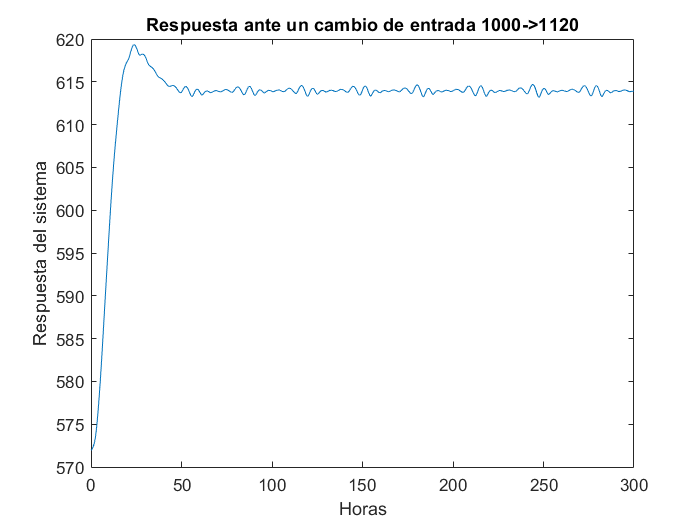

figure
clf
plot(t,y_response)
xlabel('Horas')
ylabel('Respuesta del sistema')
title('Respuesta ante un cambio de entrada 1000->1120')

**Figura 2: Respuesta a un cambio de entrada**

Con base en dicha información, nuestro anterior ingeniero decidió excitar el sistema con un periodo de muestreo de 1 hora y una señal PRBS (con un periodo igual al de muestreo) que variaba entre valores de 900 y 1120 para luego proceder a identificar un modelo apropiado para la planta, sin embargo, tuvimos que prescindir del ingeniero en este punto y el sistema no ha podido identificarse. Los datos recopilados se muestran a continuación

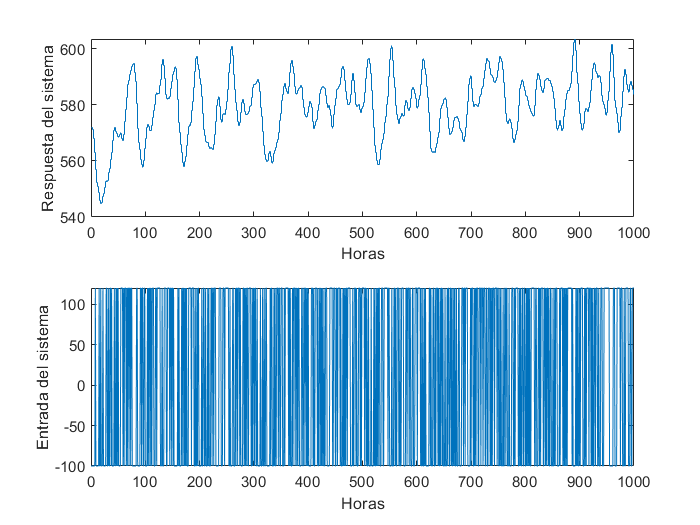

figure(3)
clf
subplot(2,1,1)
stairs(0:1000,y')
xlabel('Horas')
ylabel('Respuesta del sistema')
subplot(2,1,2)
plot(0:1000,u)
xlabel('Horas')
ylabel('Entrada del sistema')

**Figura 3:Excitación del sistema con una señal PBRS**

Nos hemos contactado con ustedes con la esperanza de que puedan evaluar la metodología que siguió nuestro anterior ingeniero (si es adecuada o si modificarían algo) y, en caso de que lo consideren posible, concluir el proceso de identificación del sistema. Les solicitamos el mayor detalle posible en sus respuestas así como en la justificación de porqué deberíamos confiar o no en el modelo que ustedes puedan identificar. Estaremos muy atentos. 

## 2. Análisis trabajo previo

En esta sección verificamos y analizamos el proceso que siguió el ingeniero anterior.

### 2.1    Periodo de muestreo y curva de linealidad

Primero calculamos el tiempo de muestreo, para esto primero escalamos la respuesta para que inicie en 0. Con estos datos calculamos el tiempo de muestreo.

aux = y_response - y_response(1);

Calculamos el valor de estabilización $y_{\textrm{ss}}$ mediante la mediana de los últimos valores (debido a que vemos que hay una leve oscilación en estado estacionario). Calculamos $t_r$ como el tiempo que toma ir desde el 10% del valor de estabilización hasta el 90% del valor de estabilización. 

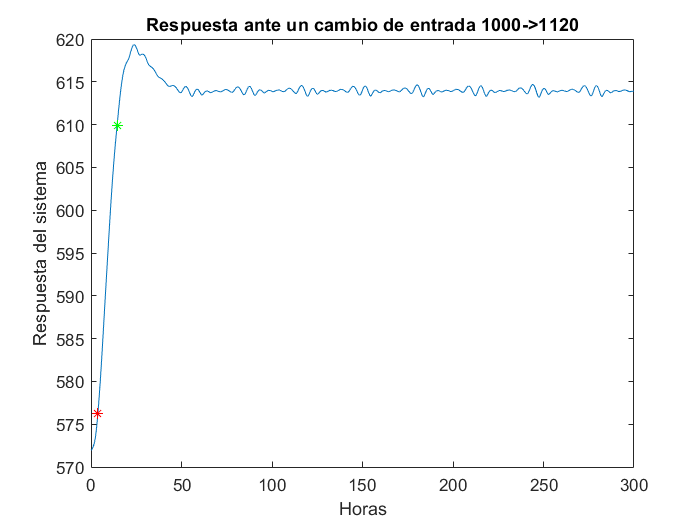

k = median(aux(1500:end));
in = find(aux >= 0.1*k,1);
fin = find(aux >= 0.9*k,1);
tr = t(fin) - t(in);
figure
clf
plot(t,y_response)
hold on;
plot(t(in),y_response(in),'r*')
plot(t(fin),y_response(fin),'g*')
xlabel('Horas')
ylabel('Respuesta del sistema')
title('Respuesta ante un cambio de entrada 1000->1120')

**Figura 4: Identificación de **$t_r$

Seleccionamos $t_s =\frac{t_r }{10}$ según el criterio visto en clase.

ts = tr/10 %criterio para determinar tiempo de muestreo

ts = 1.0600


m_sample = median(y_sample(:,150:end),2);
clf
plot(u_lineal',m_sample)
hold on;
line([900 900],[200 800])
line([1120 1120],[200 800])
x1 = 1000;
y1 = interp1(u_lineal,m_sample,x1);
x2 = 1120;
y2 = interp1(u_lineal,m_sample,x2);
m = (y2-y1)/(x2-x1);
y_line = m*(u_lineal - x2) + y2

y_line =   398.1863  401.6661  405.1458  408.6256  412.1053  415.5851  419.0648  422.5446  426.0243  429.5041  432.9838  436.4636  439.9433  443.4231  446.9028  450.3826  453.8623  457.3420  460.8218  464.3015  467.7813  471.2610  474.7408  478.2205  481.7003  485.1800  488.6598  492.1395  495.6193  499.0990  502.5788  506.0585  509.5383  513.0180  516.4978  519.9775  523.4572  526.9370  530.4167  533.8965  537.3762  540.8560  544.3357  547.8155  551.2952  554.7750  558.2547  561.7345  565.2142  568.6940


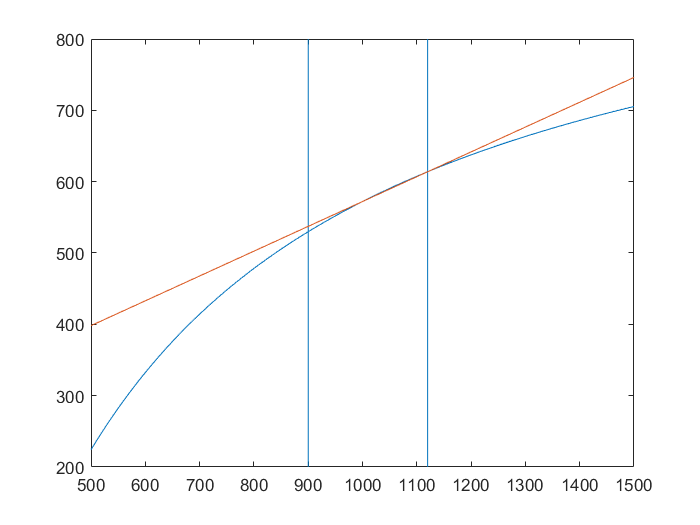

plot(u_lineal,y_line)

**Figura 5: Curva de linealidad**

Lo primero que verificamos es el periodo de muestreo fuese correcto, para encontrar el periodo se suele obtener la respuesta del sistema a un escalón y se espera que el sistema se estabilice. Sin embargo, dependiendo de las características del sistema y la presencia de ruido, es posible que el sistema no responda a una entrada escalón unitario por lo que se necesita de una entrada con una potencia adecuada. El ingeniero escogió una PRBS (la PRBS que se brindó varía de 120 hacia arriba a 100 hacia abajo) que corresponde al máximo impulso que va a utilizar.

En la figura 5 se graficó la mediana de los últimos valores de y_sample (para tener una aproximación del valor de estabilización) contra la entrada u_lineal. Suponemos que el ingeniero escogió valores en torno al punto de equilibrio en el que trabaja la empresa, de manera que el comportamiento entre estos valores fuese lineal. Se puede observar que en el rango de valores encerrado por las líneas verticales, el modelo se comporta casi linealmente y los valores escogidos para la PRBS corresponden a este rango. 

Siendo extremadamente estrictos, se podría decir que los valores escogidos para la PBRS se salen un poco de la región de linealidad. Analizando las discrepancias en la región de linealidad, podríamos decir que es posible que el máximo cambio del sistema no esté dado en un impulso de 120 sino en un impulso de 220 (el modelo hacia abajo podría responder de manera distinta). Esta posibilidad no la podemos verificar pero sería recomendable explorarla.

La pequeña discrepancia en los rangos de linealidad podría causar algunos problemas a la hora de ajustar el sistema a su equivalente modelo lineal. Sin embargo, se puede asumir que estas discrepancias no tendrán efecto en la elección del periodo de muestreo porque el teorema de dependencia continua nos garantiza que cambiar un poco el rango de linealidad no nos cambiará significativamente el periodo de muestreo. Estas ascerciones las hacemos debido a que en la Figura 1 que se nos presentó, pudimos observar que cuando el ingeniero varió la entrada entre 500 y 1500, no se observaron discontinuidades (al tratarse de una planta real asumimos que no habrá discontinuidades pero es posible que existan, de cualquier manera esto va más allá de lo que podemos verificar). 

De acuerdo a lo anterior, no estaríamos totalmente seguros de que la selección de la PRBS sea la mejor pero si consideramos que es suficientemente apropiada y es posible iniciar con la estimación y ajuste del modelo lineal.

### 2.2    Órden de excitación persistente

A continuación calculamos el orden de excitación persistente. De este cálculo observamos que tendríamos problemas al ajustar modelos de orden mayor a 25 puesto que necesitamos que el orden de excitación persistente sea al menos 2m.

pexcit(iddata(y,u',1))

ans = 50

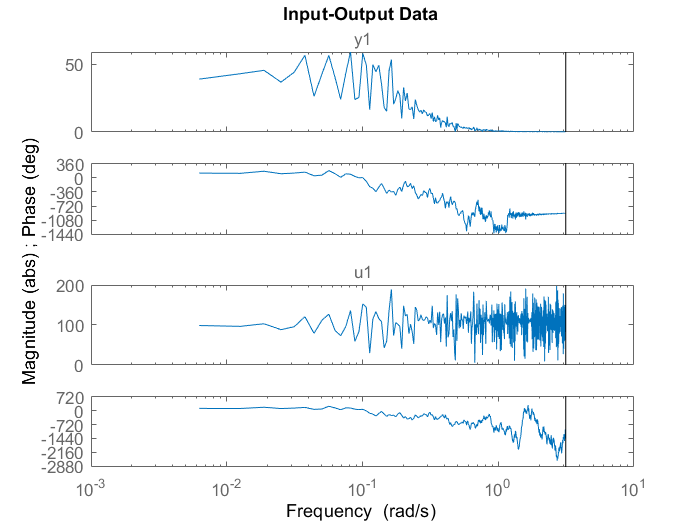

clf
Data  = fft(iddata(y,u',1));
plot(Data)

## 3. Exploración de los datos

### 3.1 Preprocesamiento de los datos

Utilizando el toolbox de identificación de sistemas realizamos el pre procesamiento de los datos. En el preprocesamiento se realiza el tratamiento de outliers, se remueven tendencias y se remueven las medias (se escalan los datos para que las condiciones iniciales sean cero )

La siguiente figura muestra los datos obtenidos con el pre procesamiento, divididos en datos para estimación (en rojo) y datos para validación (en azul claro)

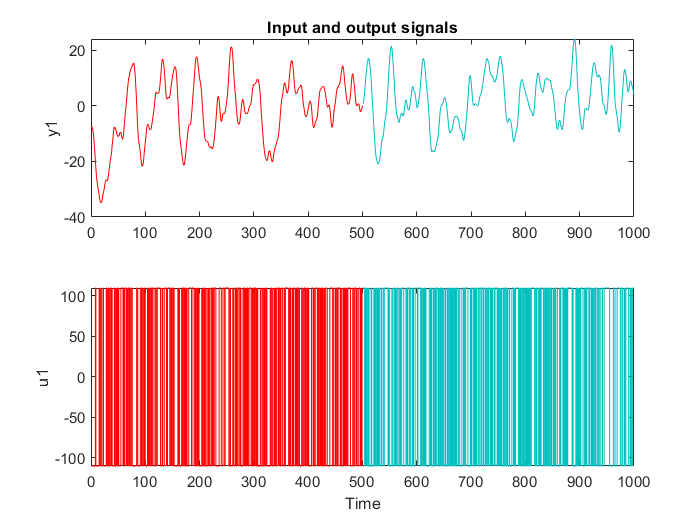

En la siguiente figura se muestra el ajuste entre la salida obtenida mediante el método de correlación y los datos de validación.

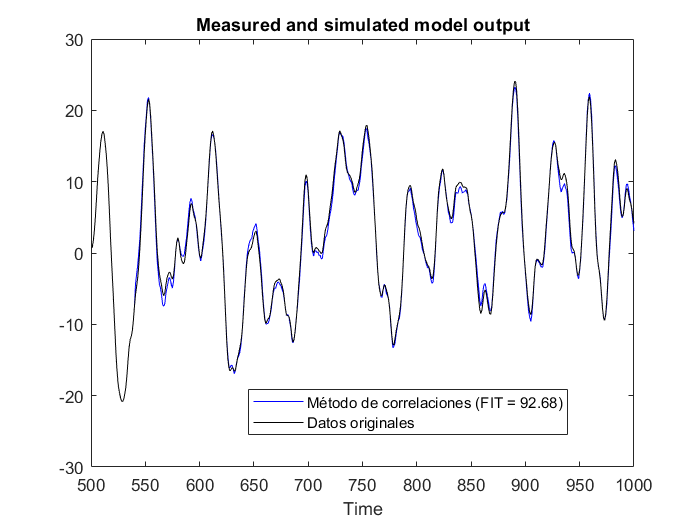

En la siguiente figura se presenta la respuesta al impulso obtenida a partir del método de correlación y los intervalos de confianza del 99%

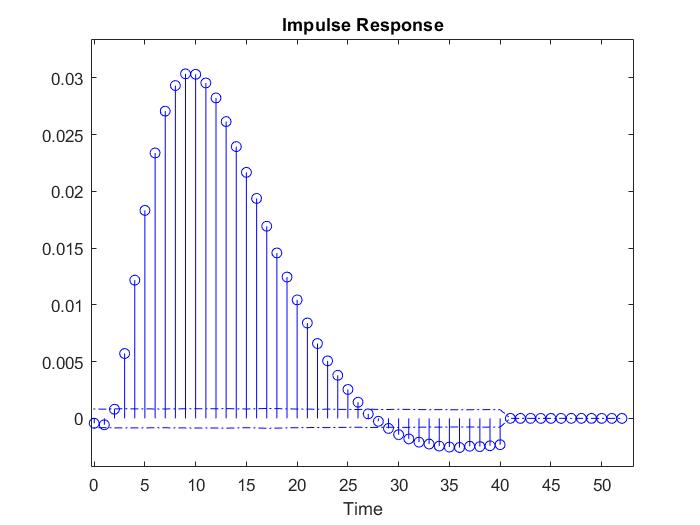

En la gráfica de respuesta al impulso podemos observar que hay dos datos al inicio dentro del intervalo de confianza (al 99%)  y un dato justo en el límite de dicho intervalo por lo que intuimos que el retardo estaría a 2 o 3 unidades de tiempo.

Para decidir sobre el valor del retardo importamos los datos pre procesados y utilizamos la función **delayest.**

load data2de.mat

Estimamos el retardo mediante la función delayest

delayest(data2de)

ans = 3

En la siguiente figura se muestra la respuesta a la frecuencia obtenida mediante el método espectral SPA (Blackman-Tuckey)

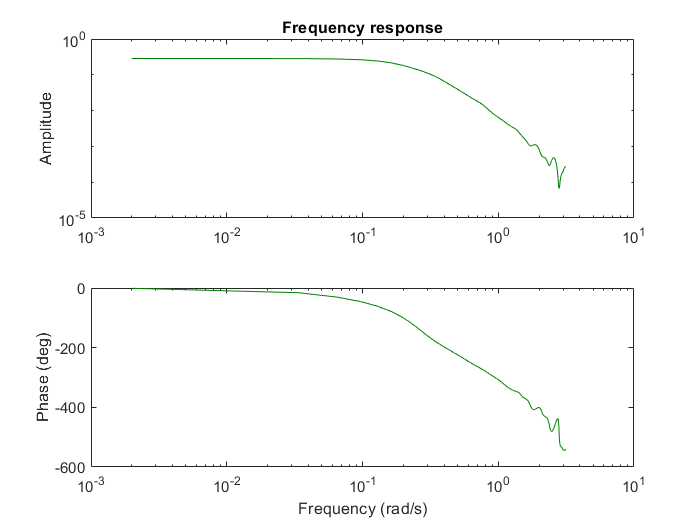

Al final de la gráfica, en las frecuencias más altas no se ve mucho ruido entonces no vemos necesidad de filtrar los datos.                

## 5 Ajuste con modelos ARX

Iniciamos explorando modelos ARX, considerando un grupo grande de modelos, fijando $\textrm{nk}=3$ 

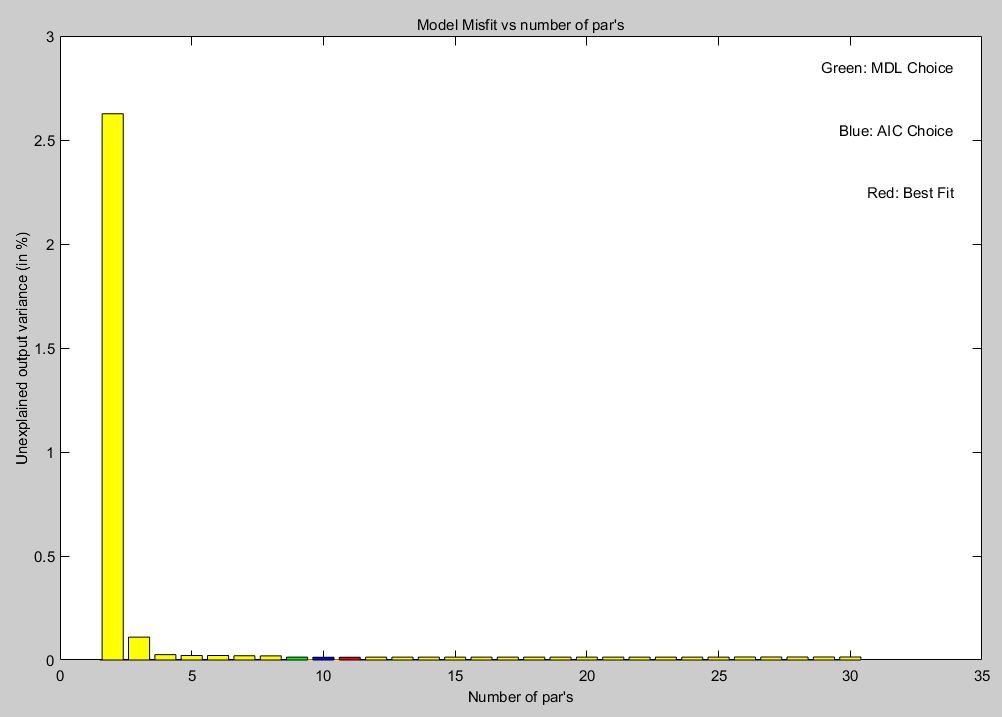

Los modelos según los criterios de la gráfica son:

- Criterio MDL: ARX543

- Criterio AIC: ARX643

- Best fit: ARX 653

Escogemos el modelo ARX543 que recomienda el criterio MDL (siguiendo el criterio de parsimonia).

A continuación se muestra el análisis de los residuos para el modelo ARX543. Es claro que en la correlación cruzada hay un pico abrupto que se sale de los intervalos de confianza (al 99%) y vuelve a entrar, por lo que tenemos indicios de que faltan ceros o no se ha estimado bien el retardo.

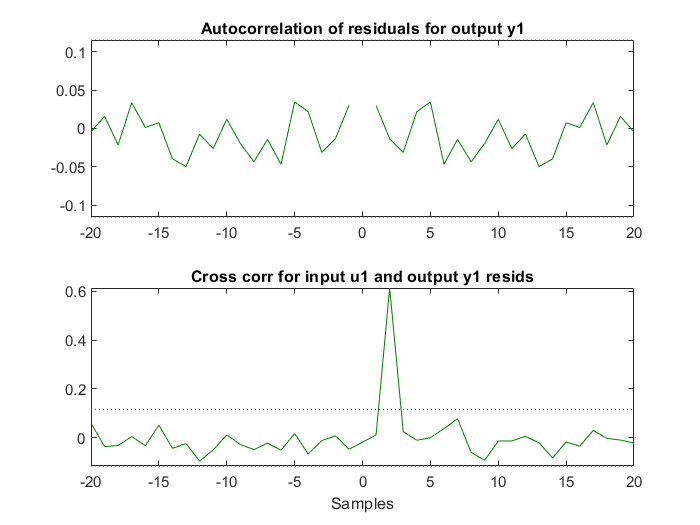

Para identificar si el problema es la falta de ceros o que se ha estimado mal el retardo, amentamos el número de ceros  y escogemos el modelo ARX653 (escogemos este modelo pues es el que recomienda el criterio Best Fit). Vemos en la siguiente figura que el modelo ARX653 (gris) presenta el mismo problema que el modelo ARX543 (verde) por lo que concluímos que al aumentar el número de ceros el modelo sigue fallando. Por tanto, es probable que se esté estimando erróneamente el retardo.

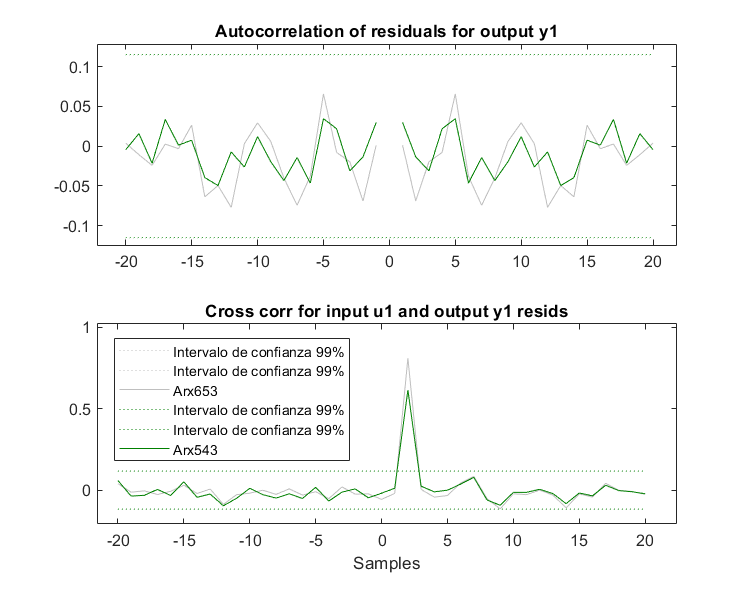

Volvemos a explorar un conjunto grande de modelos ARX, esta vez con retardo $\textrm{nk}=2$

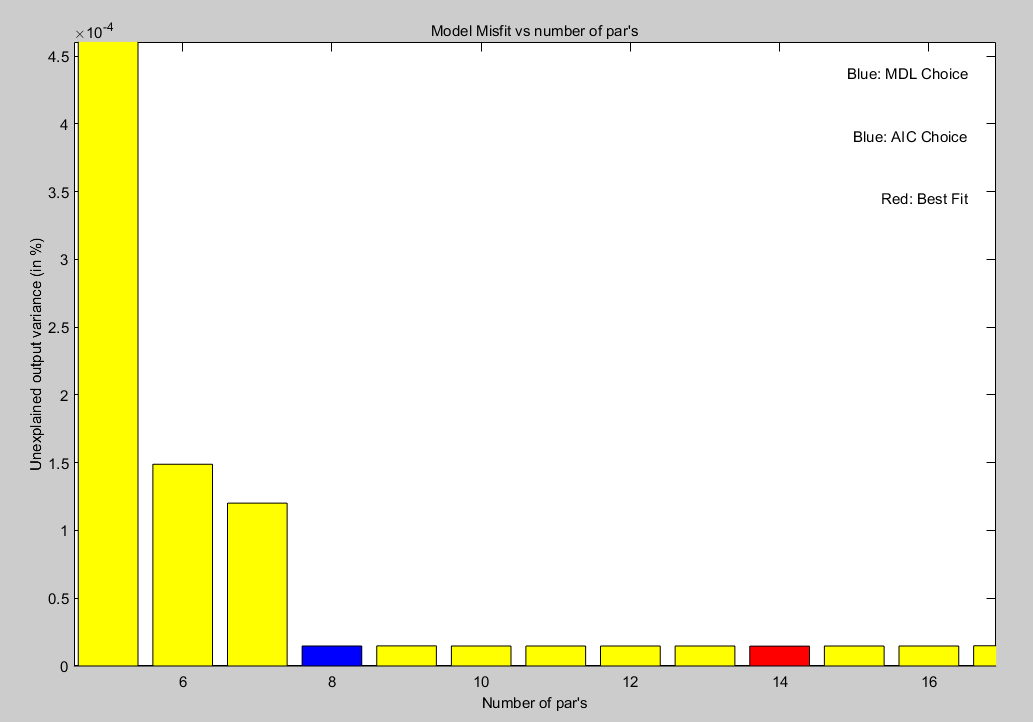

Los modelos recomendados según los criterios de la gráfica son:

- Criterio MDL/AIC :ARX 442

- Criterio Best fit: ARX 772

En la siguiente gráfica se muestra el análisis residual para los modelos ARX 442 y el modelo ARX 772. Ambos tienen el mismo pico abrupto que se sale de los intervalos de confianza (al 99%) y vuelve a entrar. Es decir, de nuevo tenemos indicios de que el retardo está mal estimado o se necesitan más ceros. Nótese que el modelo ARX 772 también presenta el mismo problema. Es decir, un modelo con más ceros sigue fallando. Por tanto, concluímos que en estos modelos también se ha estimado mal el retardo.

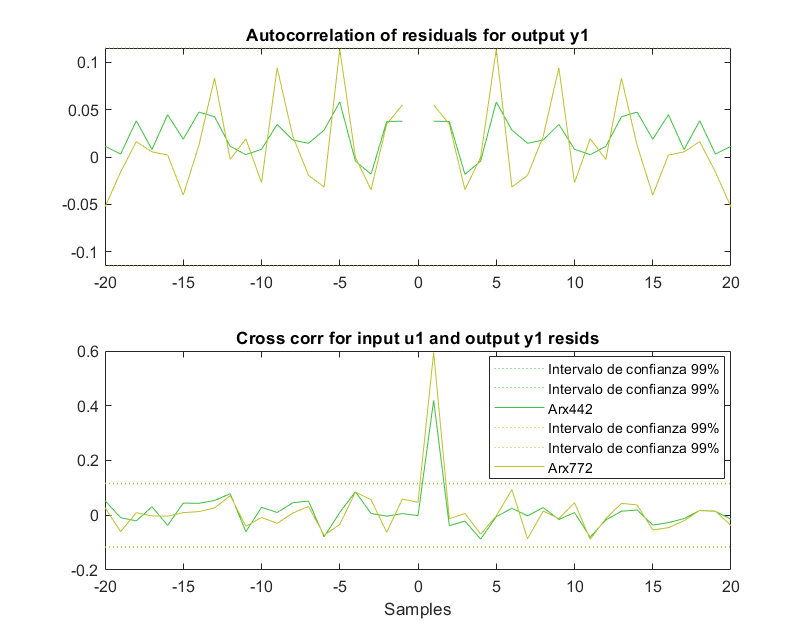

Exploramos ahora modelos ARX con retardo 1

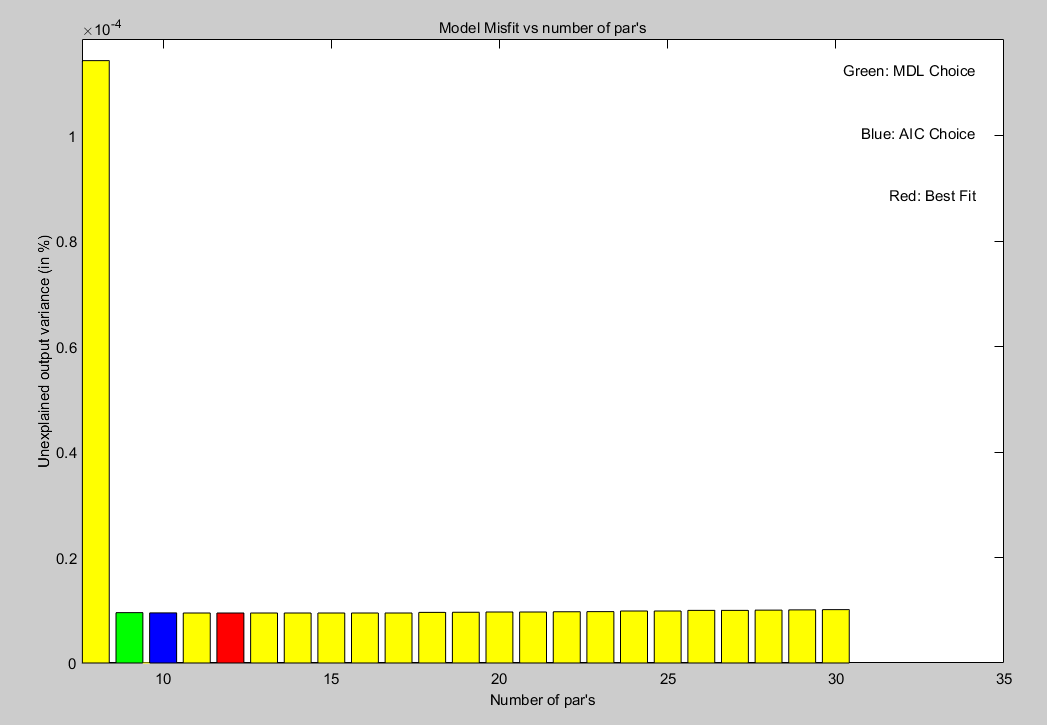

Los modelos recomendados según los criterios de la gráfica son:

- Criterio MDL :ARX 451

- Criterio AIC : ARX 551

- Criterio Best fit: ARX 661

En la siguiente figura se muestra la autocorrelación y la correlación cruzada de los residuos para los tres modelos.

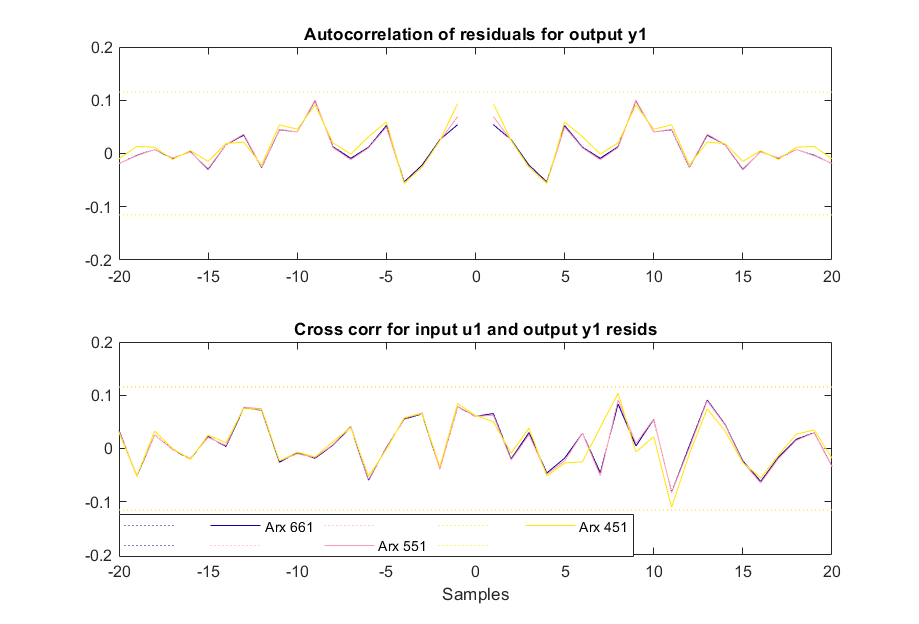

Se puede ver que la autocorrelación y la correlación cruzada están dentro de los intervalos de confianza (99%) para todos los modelos. Siguiendo el principio de parsimonia, seleccionamos el Arx 451 que es el modelo recomendado por el criterio MDL.  Este modelo es el de menor órden entre los 3 modelos recomendados.

Que el modelo pase el test de blancura signifca que el modelo es capaz de explicar la salida. En la siguiente sección presentamos los resultados y el análisis del ajuste con este modelo.

## 6 Resultados del mejor modelo ARX

La siguiente figura muestra una comparación entre el modelo Arx 451, el modelo obtenido con el método de correlaciones y los datos originales, se observa un buen ajuste. El modelo ARX 451 tiene un FIT de 94.77 mientras el obtenido con el método de correlaciones es de 92.62.

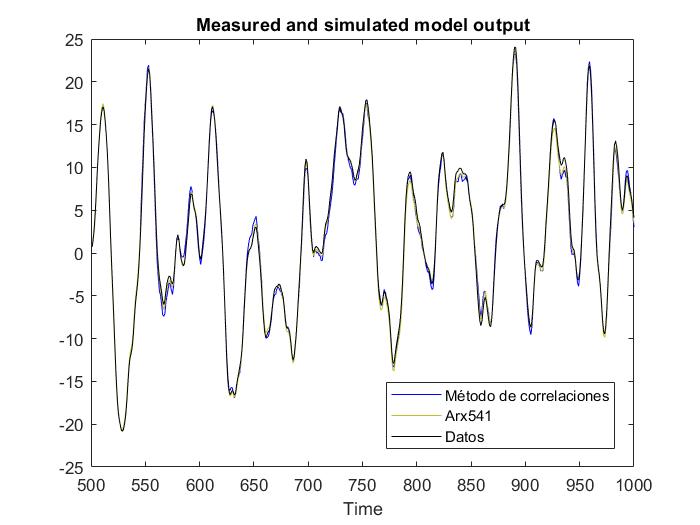

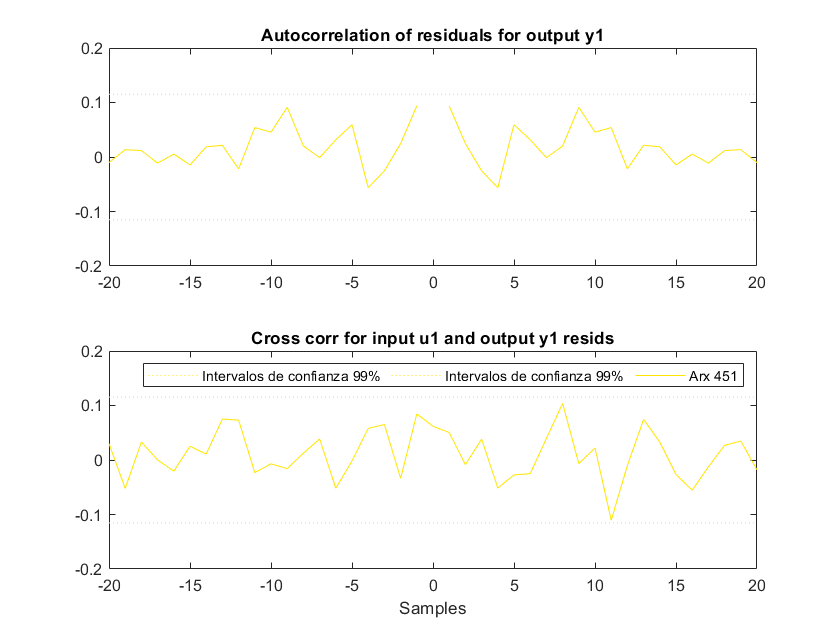

El siguiente gráfico de respuesta a la frecuencia compara el modelo ARX451 seleccionado con el modelo espectral SPA y se puede observar que hay un ajuste relativamente bueno (es menos bueno en las menores frecuencias).

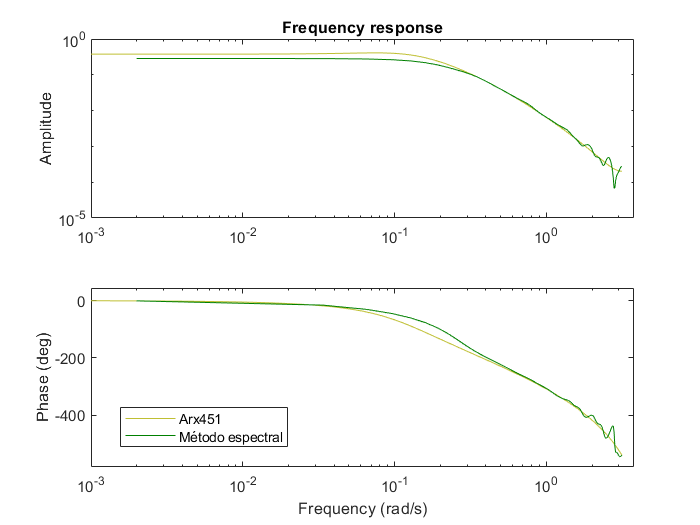

En la gráfica de la respuesta temporal se puede observar que el ajuste es muy bueno al inicio pero el ajuste es menos bueno a partir de $t=15$. En estado estacionario el ajuste es bueno.

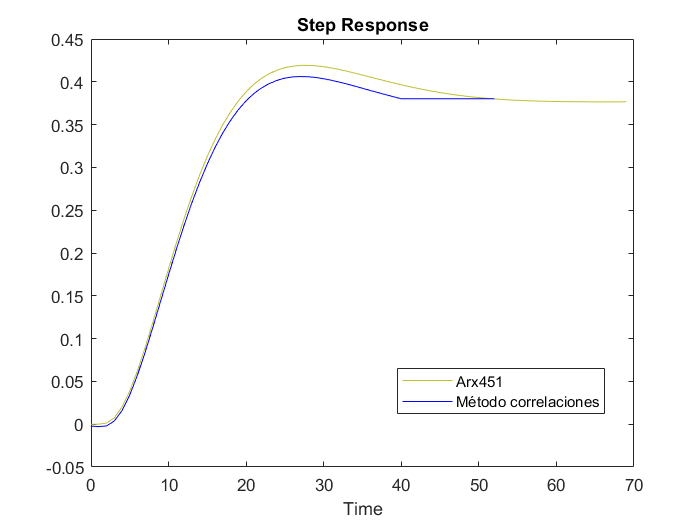

En la siguiente gráfica se muestra el mapa de polos y ceros con los intervalos de confianza del 99%

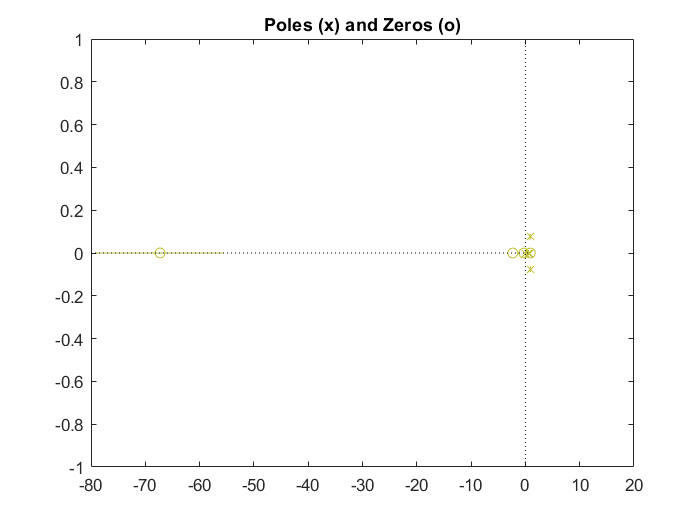

Podemos hacer zoom para identificar si los polos se encuentran en dichos intervalos

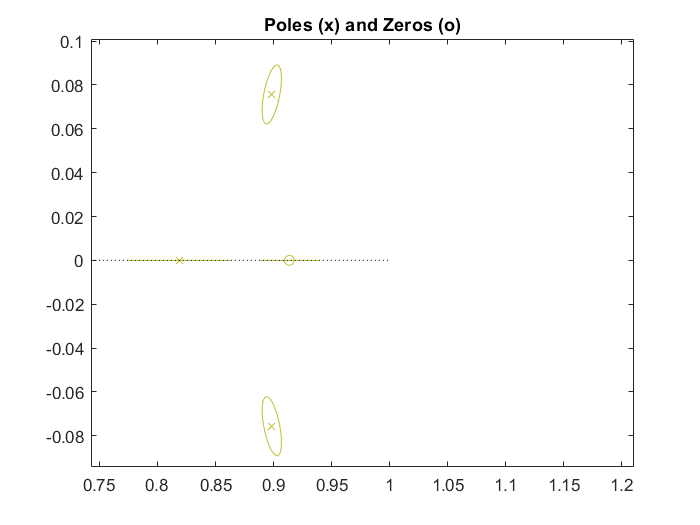

Observamos que todos los polos están en los intervalos de confianza y además, todos los polos están en el círculo unitario, por lo que sabemos que el sistema es estable. Al observar la primera gráfica, concluímos que podría haber cancelación de polos y ceros.

Opt = arxOptions;
arx451 = arx(data2de,[4 5 1], Opt);
pole(arx451)

ans =    0.0000 + 0.0000i
   0.8985 + 0.0757i
   0.8985 - 0.0757i
   0.8188 + 0.0000i
   0.5798 + 0.0000i


zero(arx451)

ans =   -67.2849
   -2.3277
    0.9135
   -0.3099


El modelo ARX obtenido es

arx451

arx451 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                     
  A(z) = 1 - 3.196 z^-1 + 3.801 z^-2 - 1.99 z^-3 + 0.386 z^-4                           
                                                                                        
  B(z) = 1.789e-05 z^-1 + 0.001235 z^-2 + 0.002045 z^-3 - 0.002044 z^-4 - 0.0007933 z^-5
                                                                                        
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=5   nk=1
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using ARX on time domain data "data2de".
Fit to estimation data: 99.98% (prediction focus) 
FPE: 8.609e-06, MSE: 8.141e-06                    


present(arx451)

                                                                                                    
arx451 =                                                                                            
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                 
                                                                                                    
  A(z) = 1 - 3.196 (+/- 0.009857) z^-1 + 3.801 (+/- 0.02237) z^-2 - 1.99 (+/- 0.01665) z^-3         
                                                                         + 0.386 (+/- 0.004008) z^-4
                                                                                                    
                                                                                                    
  B(z) = 1.789e-05 (+/- 1.185e-06) z^-1 + 0.001235 (+/- 1.2e-06) z^-2 + 0.002045 (+/- 1.242e        
                          -05) z^-3 - 0.002044 (+/- 3.165e-05) z^-4 - 0.0007933 (+/- 9.241e

Nota: Como ninguno de los errores es muy grande, trabajamos con una cifra significativa

Modelo Arx 451:


$$A\left(z\right)=1+a_1 z^{-1} +a_2 z^{-2} +a_3 z^{-3} +a_4 z^{-4}$$



$$B\left(z\right)=b_1 z^{-1} +b_2 z^{-2} +b_3 z^{-3} +b_4 z^{-4} +b_5 z^{-5}$$


donde


$$a_1 =-3\ldotp 20\pm 1\times \;{10}^{-2} \left(0\ldotp 3%\right)$$



$$a_2 =\;3\ldotp 80\pm 2\times \;{10}^{-2} \left(0\ldotp 6%\right)$$



$$a_3 =-1\ldotp 99\pm 2\times \;{10}^{-2} \left(1\ldotp 0%\right)$$



$$a_4 =\;0\ldotp 39\pm 4\times \;{10}^{-3} \left(1\ldotp 0%\right)$$



$$b_1 =1\ldotp 79\times \;{10}^{-5} \pm 1\times \;{10}^{-6} \left(5\ldotp 6%\right)$$



$$b_2 =1\ldotp 23\times \;{10}^{-3} \;\pm 1\times \;{10}^{-6} \left(0\ldotp 1%\right)$$



$$b_3 =2\ldotp 04\times \;{10}^{-3} \pm 1\times \;{10}^{-5} \left(0\ldotp 5%\right)$$



$$b_3 =2\ldotp 04\times \;{10}^{-3} \pm 3\times \;{10}^{-5} \left(1\ldotp 5%\right)$$



$$b_5 =-7\ldotp 93\times \;{10}^{-4} \pm 9\times \;{10}^{-6} \left(1\ldotp 1%\right)$$
  

Se puede observar que el coeficiente $b_1$está muy cercano a 0, por eso nos planteamos la posibilidad de reducir el modelo a un Arx442. En la siguiente figura se observa que el modelo Arx442 no pasa el análisis residual (se observa un pico abrupto que sale de los intervalos de confianza). Por tanto, optamos por quedarnos con el modelo Arx 451.

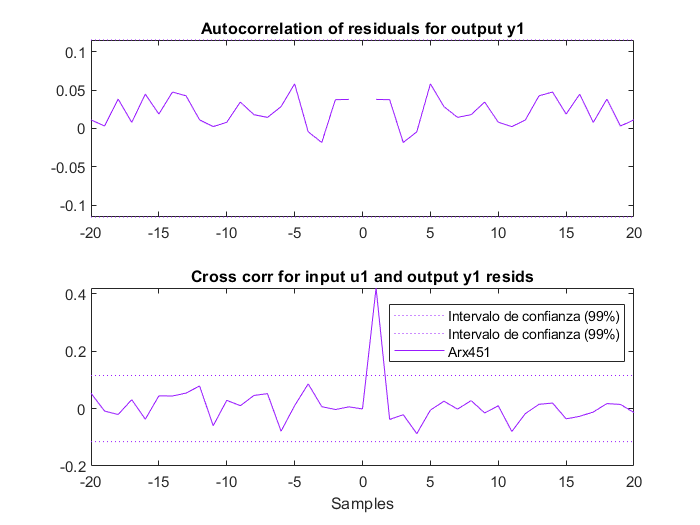

## 7 Conclusión

Como vimos en los resultados de los primeros Arx explorados (con retardo 2 y 3), es posible que las funciones por defecto como** delayest **no siempre arrojen los mejores resultados, por lo que es necesario revisar el ajuste y el análisis residual.Para identificar el mejor modelo, exploramos diferentes modelos ARX, identificando visualmente los casos en los que se estima erróneamente el retardo, hacen falta ceros o hacen falta grados de libertad. 

 El modelo Arx 451 encontrado en la sección anterior pasa el test de blancura y por tanto podemos afirmar que el modelo es capaz de explicar la salida, además obtuvimos ajustes relativamente buenos para la respuestat temporal y la respuesta en frecuencia.